przed wykonaniem zadan włacz w matlabie log za pomoca polecenia: 

diary(0log indeks lab30). Podaj nr Twojego indeksu

diary('log_184698_lab3')

Zadanie A:

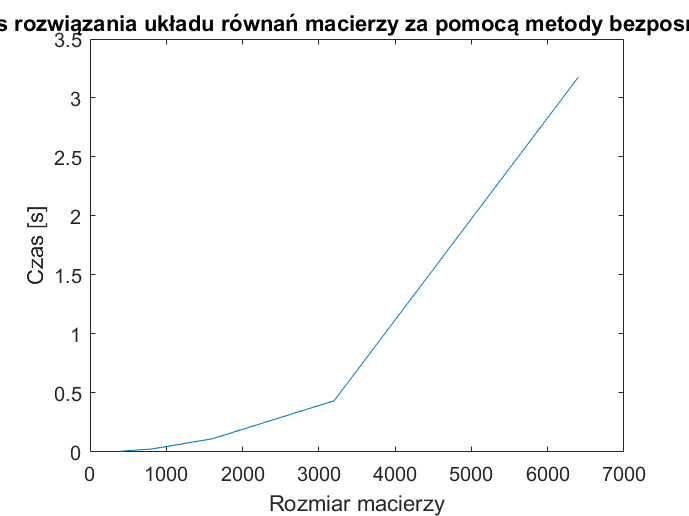

N = [400, 800, 1600, 3200, 6400];  % N = [500, 1000, 3000, 6000, 12000];
d = 0.85;
density = 10;
my_index = 184698;

for i = 1:length(N)
    [Edges] = generate_network(N(i), density, my_index);
    I = speye(N(i));
    B = sparse(Edges(2,:), Edges(1,:), 1, N(i), N(i));
    L = sum(B);
    A = speye(N(i))./L;
    b = ones(N(i), 1).* ((1-d)/N(i));
    M = sparse(I - d*B*A);

    %poczatek pomiaru czasu
    tic
    %metoda bezpośrednia
        r = M\b;
    %koniec pomiaru czasu
    timeArr(i) = toc;
end
plot(N, timeArr)
xlabel("Rozmiar macierzy");
ylabel("Czas [s]");
title("Czas rozwiązania układu równań macierzy za pomocą metody bezposredniej");
saveas(gcf, 'zadD_184698.png');

def funkcji generate_network

function [Edges] = generate_network(N, density, my_index)

Edges = randi(N, 2, N * density) ;

Edges(:, find((Edges(1,:) - Edges(2,:))==0))=[];     % usuniecie linkow - gdzie strona wskazuje na sama siebie.

Edges_temp = sortrows(Edges'); % sortowanie, zeby ulatwic usniecie zdublowanych polaczen.
d_connections = find(sum(abs(Edges_temp(2:end,:) - Edges_temp(1:end-1,:)),2) == 0);   % wyszukanie zdublowanych polaczen.
Edges_temp(d_connections,:) = [];    % usuniecie zdublowanych polaczen.
Edges = Edges_temp';

Sites_uniq = unique(Edges(1,:));
nr_of_end_sites = 0;

for k = 1:N
    if ~ismember(k, Sites_uniq)
        nr_of_end_sites = nr_of_end_sites + 1;
        Edges = [Edges [[ones(1,N-1) * k]; [1:k-1 k+1:N]]];
    end
end

% disp(['* Liczba stron koncowych: ', num2str( nr_of_end_sites)])

end